clear
clc
close all
load("Data_Problem1_regression.mat");

Tnew = (8*T1 + 7 *T2 + 7*T3 + 6*T4 + 4*T5)/(8+7+7+6+4);

dataset1 = zeros(3000,3);
dataset2 = zeros(3000,3);
dataset3 = zeros(3000,3);


for i  = 1:3
    for j = 1:3000
        index = randi([1,size(X1,1)]);
        dataset1(j,i) = X1(index);
        dataset2(j,i) = X2(index);
        dataset3(j,i) = Tnew(index);
    end
end

fig1 = tiledlayout(2,3);
nexttile;
plot3(dataset1(:,1),dataset2(:,1),dataset3(:,1),'r.');
title('Training set');
nexttile;
plot3(dataset1(:,2),dataset2(:,2),dataset3(:,2),'r.');
title('Validation set');
nexttile;
plot3(dataset1(:,3),dataset2(:,3),dataset3(:,3),'r.');
title('Test set');
nexttile([1,3]);

x = dataset1(:,1);
y = dataset2(:,1); 
z = dataset3(:,1);

del = delaunay(x,y);

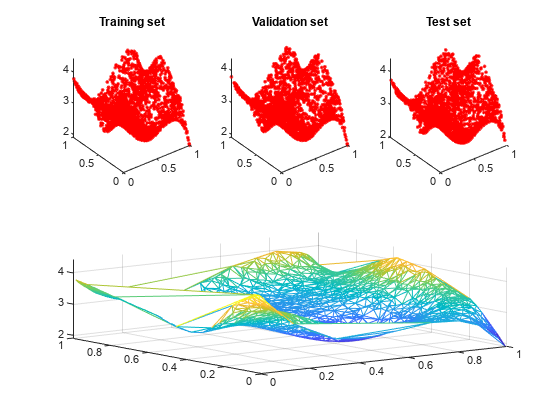

trimesh(del, x, y, z);

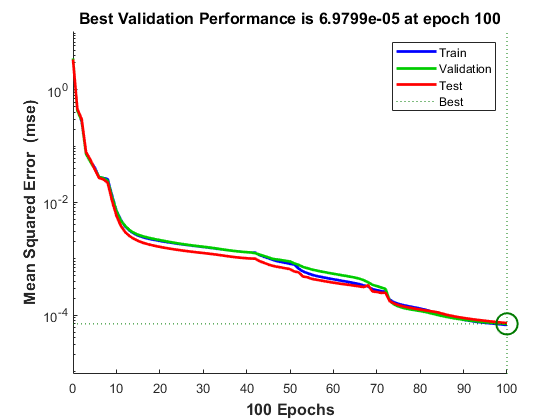



numN = 10; %number of neurons
%Training 1
trainAlg1 = 'trainlm';
net1 = feedforwardnet([numN, numN/2],trainAlg1);
net1.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net1=configure(net1,Xcomb',dataset3(:,1)');

[net1, tr] = train(net1, Xcomb', dataset3(:,1)');

plotperform(tr)

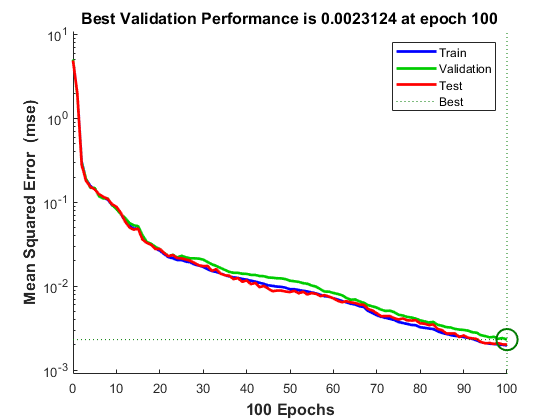


numN = 10; %number of neurons
%Training 2
trainAlg2 = 'trainbfg';
net2 = feedforwardnet([numN, numN/2],trainAlg2);
net2.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net2=configure(net2,Xcomb',dataset3(:,1)');

[net2, tr] = train(net2, Xcomb', dataset3(:,1)');

plotperform(tr)

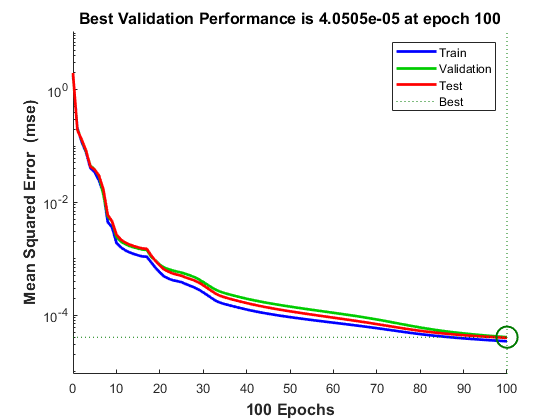


numN = 10; %number of neurons
%Training 3
trainAlg3 = 'trainscg';
net3 = feedforwardnet([numN, numN/2],trainAlg3);
net3.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net3=configure(net1,Xcomb',dataset3(:,1)');

[net3, tr] = train(net3, Xcomb', dataset3(:,1)');

plotperform(tr)

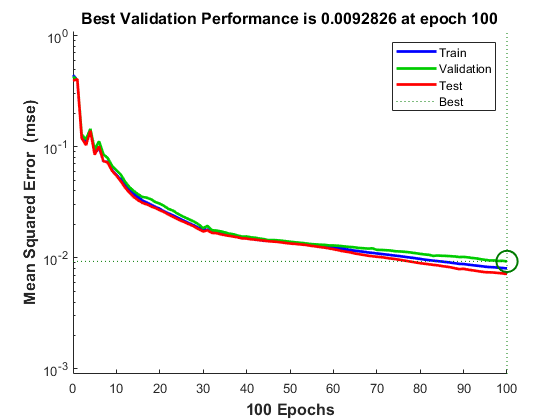


numN = 10; %number of neurons
%Training 4
trainAlg4 = 'trainrp';
net4 = feedforwardnet([numN, numN/2],trainAlg4);
net4.trainParam.epochs = 100;
Xcomb = horzcat(dataset1(:,1), dataset2(:,1));

net4=configure(net4,Xcomb',dataset3(:,1)');

[net4, tr] = train(net4, Xcomb', dataset3(:,1)');

plotperform(tr)

Xcomb1 = horzcat(dataset1(:,2), dataset2(:,2))';


netVal1 = sim(net1,Xcomb1);
netVal2 = sim(net2,Xcomb1);
netVal3 = sim(net3,Xcomb1);
netVal4 = sim(net4,Xcomb1);
%trimesh(tri, x, y, netVal3, 'EdgeColor', 'black');
%plot3(dataset1(:,2), dataset2(:,2),netVal3, 'k.') %b = blue / k = black

fig2 = figure; tiledlayout(2,4); sgtitle({'Evaluation exercise sesion 1 section 2';''});

nexttile([1,2]); x = DataSets(1,:,1); y = DataSets(1,:,2); z = DataSets(1,:,3); tri = delaunay(x,y); trimesh(tri, x, y, z, 'EdgeColor', 'red'); title('Training data'); nexttile([1,2]); x = DataSets(2,:,1); y = DataSets(2,:,2); z = DataSets(2,:,3); tri = delaunay(x,y); trimesh(tri, x, y, z, 'EdgeColor', 'green'); title('Test data');

 % Create scatteredInterpolant object

F = scatteredInterpolant(dataset1(:, 2), dataset2(:, 2), netVal1');


% Generate a grid of points for interpolation
[X, Y] = meshgrid(min(dataset1(:, 2)):0.1:max(dataset1(:, 2)), min(dataset2(:, 2)):0.1:max(dataset2(:, 2)));

% Evaluate the interpolant on the grid
Z = F(X, Y);

% Plot the interpolated surface
figure;
mesh(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Interpolated Surface');


%Validate training 1
% netVal1 = sim(net1,[DataSets(2,:,1); DataSets(2,:,2)]);
postregm(netVal1,dataset3(:,2)');
title(sprintf('Levenberg-Marquardt'));

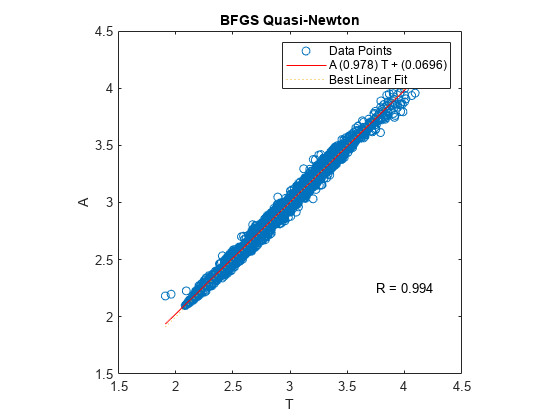


%Validate training 2
% netVal2 = sim(net2,[DataSets(2,:,1); DataSets(2,:,2)]);
postregm(netVal2,dataset3(:,2)');
title(sprintf('BFGS Quasi-Newton'));


%Validate training 3
% netVal3 = sim(net3,[DataSets(2,:,1); DataSets(2,:,2)]);
postregm(netVal3,dataset3(:,2)');
title(sprintf('Scaled Conjugate Gradient'));


%Validate training 4
% netVal4 = sim(net4,[DataSets(2,:,1); DataSets(2,:,2)]);
postregm(netVal4,dataset3(:,2)');
title(sprintf('Resilient Backpropagation'));